# MAT188 - Topic 2 Assignment

Name: Somesh Karthi

Student number: 1007935558

## Introduction

For this assignment we will be looking at the two-link robotic arm shown in Figure 1 and the animation below. The first link rotates around the origin and the second link rotates around the end of the first link.

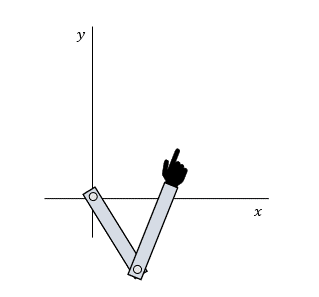

You will be given the lengths of the links $L_1$ and $L_2$, as well as their angles relative to the horizontal axis $\theta_1$ and $\theta_2$. Using this information, the goal is to calculate the x,y-coordinates of the hand at the end of the second link as shown in Figure 1c.

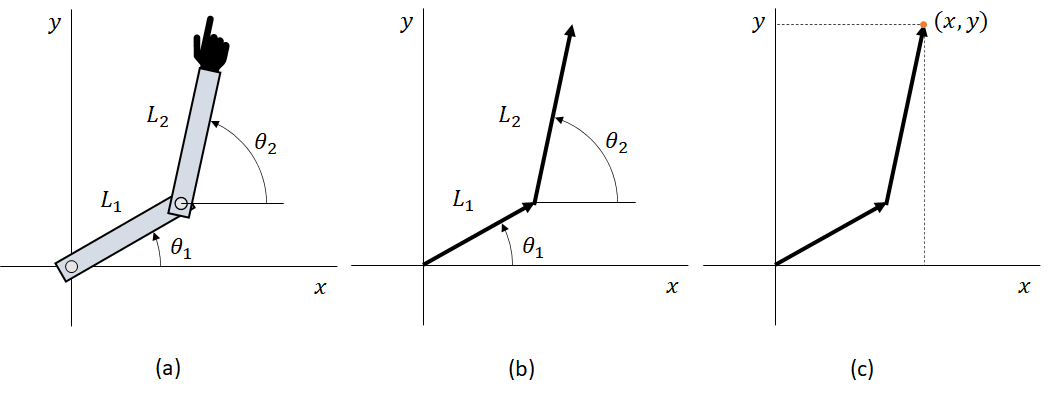

**Figure 1:** (a) diagram of the two-link robotic arm (b) simplified diagram - each arrow represents one of the links (c) x,y-coordinates of the hand (to be calculated)

This assignment consists of three parts. In each of the parts, you will

- Part 1: load data from a CSV file and visualize the provided data

- Part 2: write a function to calculate the x and y displacement of a single link given its length and angle

- Part 3: compute the x,y-coordinates of the hand using the function from Part 2

## Part 1: Load and Visualize Data

The first step is to load the data from the CSV file into the workspace and to define variables for the lengths of the two links.

The data is provided to you in `data.csv` which can be downloaded from Quercus. This file contains the values of  $\theta_1$ and $\theta_2$ at different points in time. The first column contains the values of $\theta_1$ **in degrees** and is labelled `theta1`. The second column contains the values of $\theta_2$ **in degrees** and is labelled `theta2`. Each entry (row) in this table corresponds to the angles at a different point in time.

Make sure that this MLX file and `data.csv` are saved in the **same folder**.

### 1.1 Define variables for the lengths of the two links

The lengths of the two links are $L_1 =L_2 =10\;\textrm{cm}$. Variables `L1` and `L2` representing the lengths of the links are defined below. You do not need to do anything for this part.

L1 = 10; % length of the first link in cm
L2 = 10; % length of the second link in cm

### 1.2 Load data from the CSV file provided

Import data from the CSV file provided** as a table** to a variable called `data`. Recall that in the lab exercise, you used `readtable` to import data from a CSV on the internet using its URL. Now we are importing from a local file saved in the same folder, so instead of the URL you need to use the file name (data.csv) to specify the file that you want to load from. 

data = readtable('data.csv');

### 1.3 Make a polar plot to visualize the trajectory of the first link

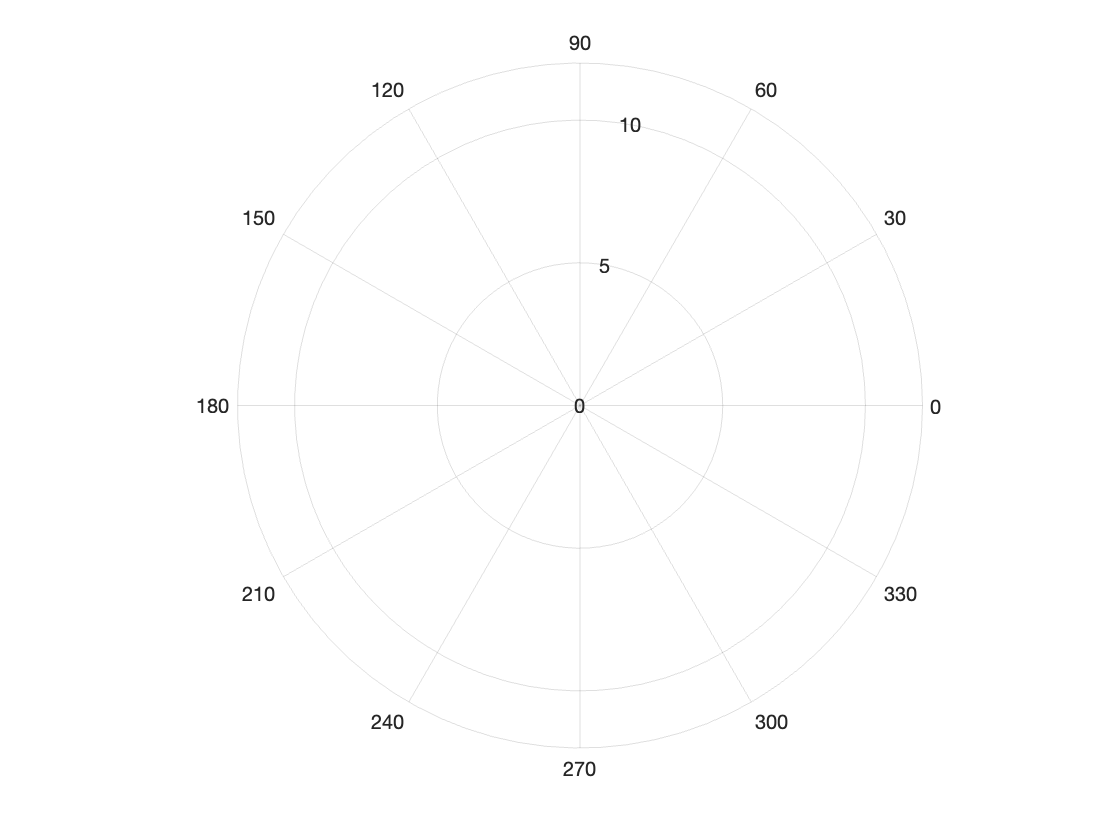

radtheta1 = deg2rad(data.theta1);
polarplot(radtheta1,L1);

## Part 2: Polar to Cartesian for a Single Link

In the data, you are given a series of angles for each of the links. You also know the lengths of each of the links. With this information, you can calculate the x,y-coordinates of the end of the link.

To start, let us consider only one of the links. Let $\rho$ be the length of the link and $\theta$ be its angle relative to the horizontal axis as shown in Figure 2a. You will write a function which uses $\theta$ and $\rho$ to compute the x and y displacements of the link (Figure 2b).

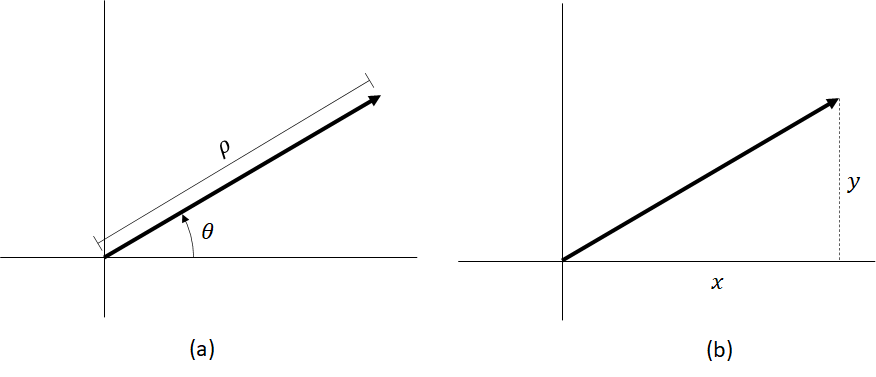

**Figure 2:** (a) polar coordinates (b) cartesian coordinates

### **A bit of math to help you get started**

One way to get the values of x and y is to start with a vector $\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$which has length 1 and lies horizontally along the positive x axis. If we transform $\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$by rotating it counterclockwise by the angle $\theta$ and stretching it by a factor of $\rho$, then we will arrive at the vector shown in Figure 2 expressed in cartesian coordinates - which is exactly what we want.

$\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\rho \left\lbrack \begin{array}{cc}
\;\cos \;\theta  & -\sin \;\theta \\
\sin \;\theta  & \cos \;\theta 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack =\rho \left\lbrack \begin{array}{c}
\cos \;\theta \\
\sin \;\theta 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\rho \;\cos \;\theta \\
\rho \;\sin \;\theta 
\end{array}\right\rbrack \to$ this tells us that $x=\rho \;\cos \;\theta$ and $y=\rho \;\sin \;\theta$

### 2.1 Write the `get_xy_coordinates` function

Scroll down to the **Functions** section at the bottom of this document and implement the `get_xy_coordinates` function which computes the x and y displacements of the link given a vector of angles `theta` and the length lf the link `rho`.

The function takes in **two inputs**: 

- `theta` - a column vector (`N x 1`) containing the angles of the link in radians

- `rho` - a scalar, the length of the link

The function produces **two outputs**:

- `x` - a column vector (`N x 1`) containing x displacements of the link

- `y` - a column vector (`N x 1`) containing y displacements of the link

**Important: **You may **not** use the `pol2cart` function in your implementation and you will not recieve any marks for this part if you do. You will be using `pol2cart` to verify that your function works correctly. 

### 2.2 Verify that your function works

Make sure you have loaded the data correctly in Part 1 and then run the following code block to verify that your `get_xy_coordinates` function works correctly. The points generated using the `get_xy_coordinates` (blue circles) and `pol2cart` (red crosses) should overlap exactly.

**You do not need to make any changes to the code in this section **but please do run it to demonstrate the functionality of your function.

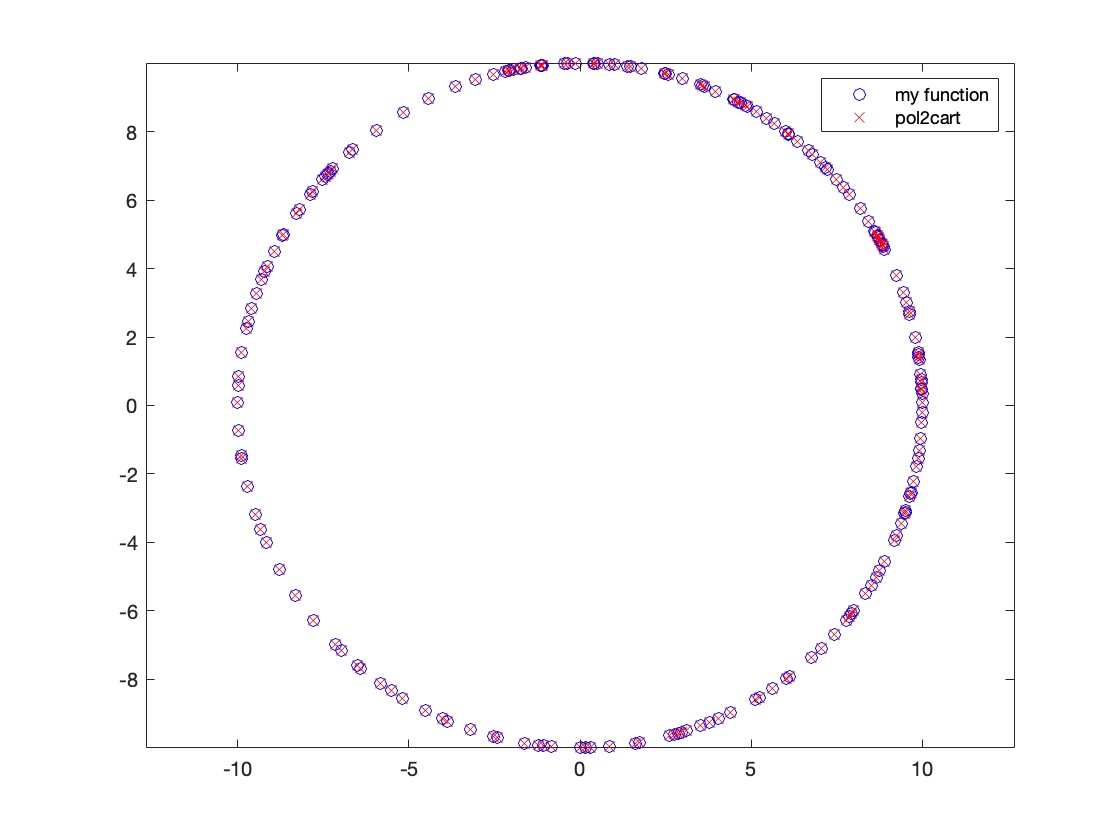

% compute the xy coordinates of first link using get_xy_coordinates
[x_myfunc, y_myfunc] = get_xy_coordinates(deg2rad(data.theta1), L1);

% compute the xy coordinates of first link using pol2cart
[x_pol2cart, y_pol2cart] = pol2cart(deg2rad(data.theta1), L1);

% plot both sets of coordinates together
plot(x_myfunc, y_myfunc, "bo")
hold on
plot (x_pol2cart, y_pol2cart, "rx")
hold off
axis("equal")
legend(["my function", "pol2cart"])

## Part 3: Forward Kinematics of the Two-Link Robot

Almost there! For this last part, you will compute the x,y-coordinates of the hand at the end of the second link, update your data table, and visualize your results.

### 3.1 Compute the x,y-coordinates and update your table

First, use the angles $\theta_1$ and $\theta_2$ in `data` (the table you loaded in Part 1) and the function you wrote in Part 2 to find the x,y-coordinates of the hand for each entry in `data`. Then, update the table `data` by adding two columns to store the x and y coordinates that you computed. Make sure to display the updated table to demonstrate that you have done this successfully.

**Hint: **To calculate the location of the hand, you can calculate the displacements of the two links individually (Figure 3a) and then take the sum (Figure 3b). 

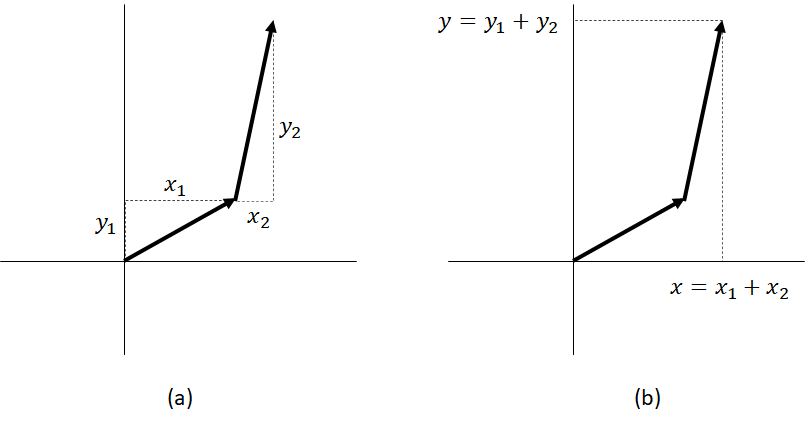

**Figure 3:** (a) displacements of individual links (b) total displacement of both links

**Please write your code below. **For this part, you may use **either** the  `get_xy_coordinates` function that you wrote or the built-in function `pol2cart`. 

[xcoordinate1, ycoordinate1] = get_xy_coordinates(deg2rad(data.theta1), L1);
[xcoordinate2,ycoordinate2] = get_xy_coordinates(deg2rad(data.theta2),L2);


### 3.2 Plot the trajectory

Plot your x and y coordinates to draw a picture.

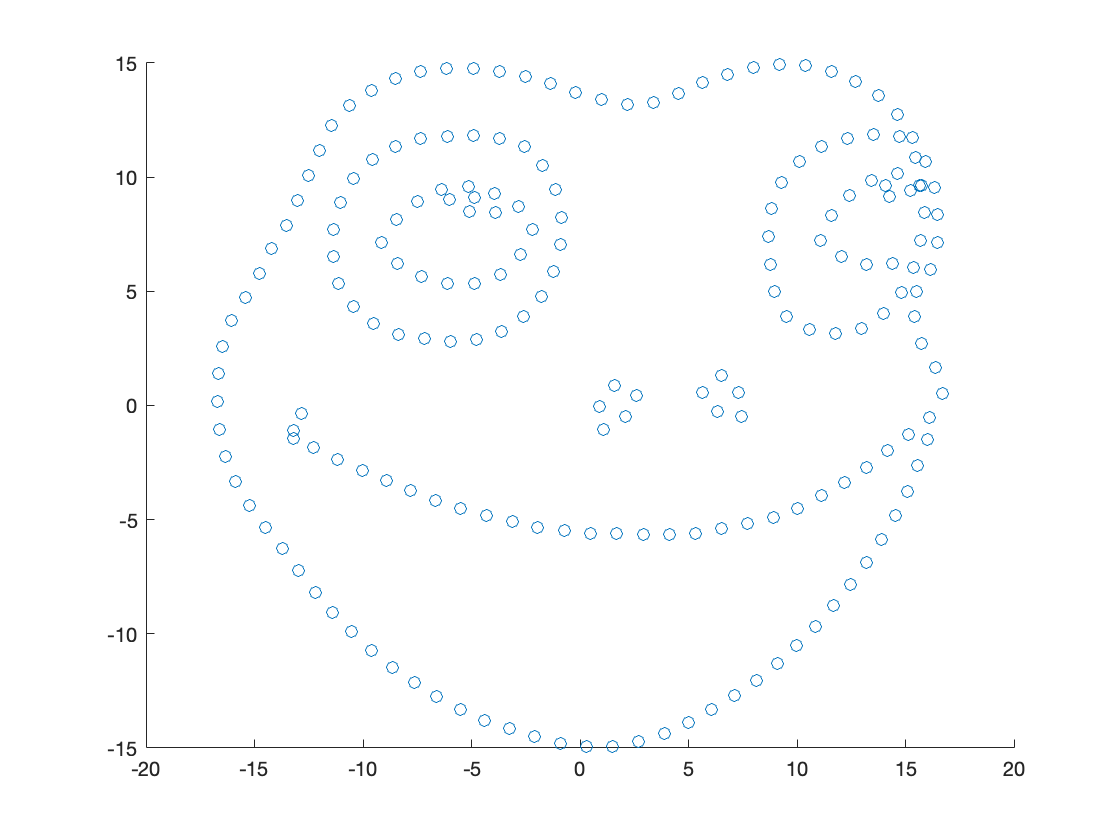

scatter(xcoordinate1+xcoordinate2, ycoordinate1+ycoordinate2);

## Functions

This is the function you need to write for Part 2.1

Inputs:

- `theta` - a column vector (`N x 1`) containing the angles of the link in radians

- `rho` - a scalar, the length of the link

Outputs:

- `x` - a column vector (`N x 1`) containing x displacements of the link

- `y` - a column vector (`N x 1`) containing y displacements of the link

function [x, y] = get_xy_coordinates(theta, rho)
x = rho*cos(theta);
y = rho*sin(theta);
end